## Test client to MIAerConn

Define variables

 
clear
commands = ["{""setadd"":""166.182.234.000""}",
            "{""disconnect"":""station""}",
            "{""disconnect"":""service""}"];

Connect to command channel

 

comClient = tcpclient("localhost",3000);

Send command and get the ack signal back

command = commands(1);

 
write(comClient,command);
datachr = char.empty;
waiting_for_ack = true;
while waiting_for_ack
    while isempty(datachr)
        datachr = read(comClient,comClient.NumBytesAvailable,"char");
    end
    datastr=convertCharsToStrings(datachr);
    disp("Received: "+ datastr);
    datastr=erase(datastr,"PING,");
    if contains(datastr,"ACK:")
        waiting_for_ack = false;
    end
end

Received: ACK:1,


disp("Command received by server");

Command received by server


Connect to stream channel

 

streamClient = tcpclient("localhost",3001);

Get the data streamed

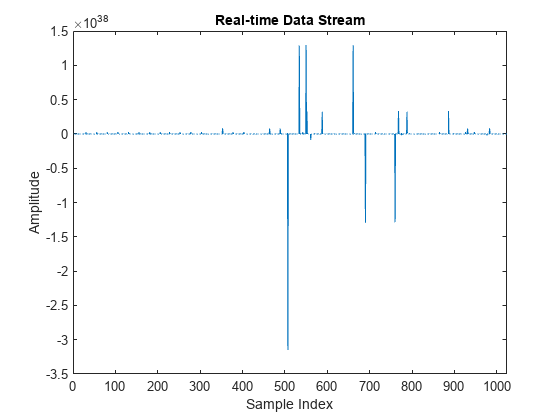

 

rawDatastream = read(streamClient, 4096, "uint8");
dataFloats = typecast(datastream, 'single');
h = plot(dataFloats);
title('Real-time Data Stream');
xlabel('Sample Index');
xlim([0 1024]);
ylabel('Amplitude');

% Continuously update the plot
keep_plotting = true;
while keep_plotting
    datastream = read(streamClient, 4096, "uint8");
    dataFloats = typecast(uint8(datastream), 'single');
    set(h, 'YData', dataFloats);
    drawnow; 
end


Test typecast

data = [0.0, 1.0, 0.0, -1.0, 0.0]; 

dataBytes = typecast(single(data), 'uint8');

trace = char(dataBytes);

disp('Encoded data:');

Encoded data:


disp(trace);

      □?      □¿    


dataBytes = uint8(trace);

% Convert the uint8 byte array back to the original single precision float array
recovedData = typecast(dataBytes, 'single');

% Display the result
disp('Recovered data:');

Recovered data:


disp(recovedData);

     0     1     0    -1     0



Close the TCP connection if needed

clear streamClient;
